Projeto de ES020-Tópicos em Engenharia Mecatrônica I

clc;clear;close all force;
RA='225295';
d=digitosRA(RA)

d =      2     2     5     2     9     5


No código acima, a string RA é fracionada e transformada num array de inteiro para cálculos futuros.

[L,Izz,M0,b,h]=dados_problema(d)

L = 95

Izz = 0.1913

M0 = 22000

b = 0.5400

h = 1.6200

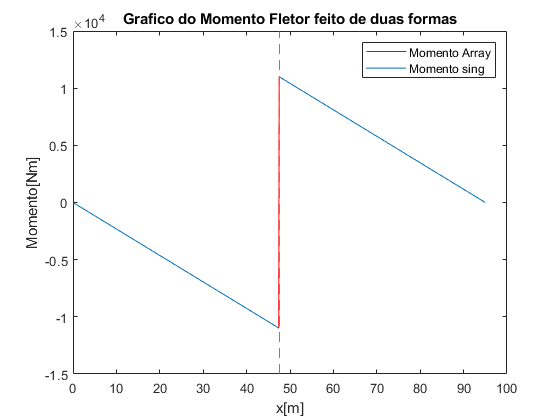

E=210e9;
P=M0/L;
x=0:0.1:L;
Mz=momento(P,L,M0);
plot(x,Mz,'r');
hold on;
Mz=@(x) P*L-M0-P*x+M0*sing((x-L/2),0);
fplot(Mz,[0 L]);
hold off;
title('Grafico do Momento Fletor feito de duas formas')
xlabel('x[m]');
ylabel('Momento[Nm]');
legend('Momento Array','Momento sing');

Mz_inv=@(x) -P*L-M0-P*x+M0*sing((x-L/2),0)

Mz_inv = function_handle with value:
    @(x)-P*L-M0-P*x+M0*sing((x-L/2),0)


x_Mz_max=fminbnd(Mz_inv,0,90)

x_Mz_max = 47.5000

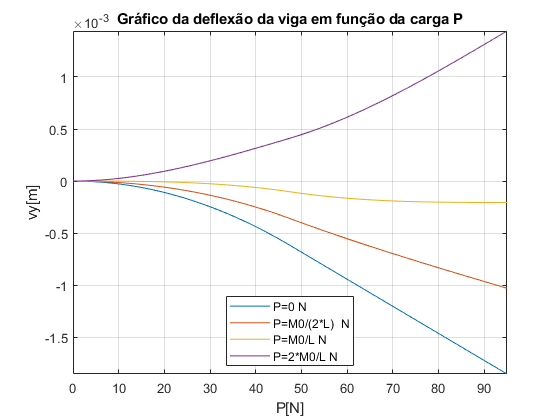

deflexao(M0,L,Izz,E);

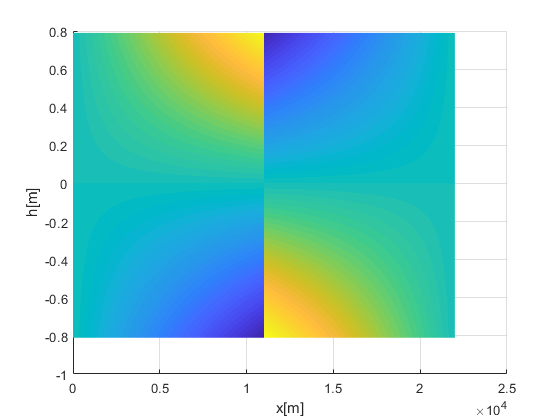

tensao_graph(L,M0,h,Izz)

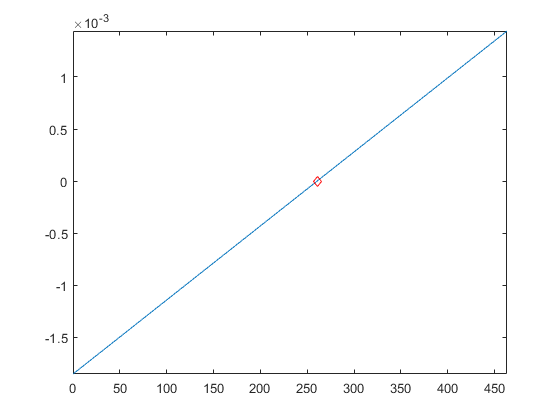

raiz = 260.5263

raiz=grafico_extremidade(L,M0,E,Izz)

raiz

raiz = 260.5263

grafico da extremidade ebla bla bla 


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the default value of the optimality tolerance, and 
constraints are satisfied to within the default value of the constraint tolerance.

<

ans =    94.0100   -0.0002



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the default value of the optimality tolerance, and 
constraints are satisfied to within the default value of the constraint tolerance.

<

ans =     0.9900    0.0000


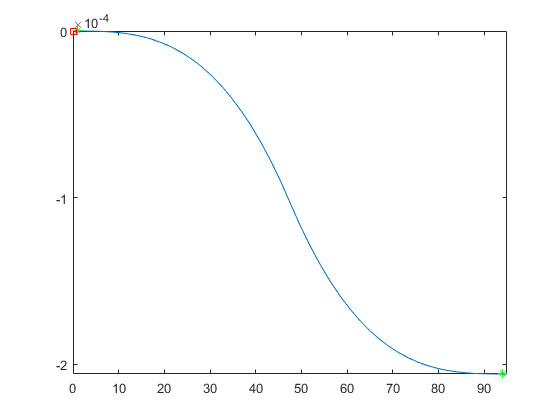

deflexao_maxima(M0,L,E,Izz);

g=9.81;
A=b*h;
rho=7850;
w0=rho*A*g;
P=M0/L;
% [L 1 0;(3L/2) 1 0;-1 0 -1][RA MA RD]=[w0(L^2/2)-M0;wo((3/2)^2)/2-M0-P((3l/2)-L);-wo(3L/2)+P]
A=[L 1 0;(3*L)/2 1 0;-1 0 -1]

A =    95.0000    1.0000         0
  142.5000    1.0000         0
   -1.0000         0   -1.0000


b=[((w0*(L^2)/2)-M0);(w0*((3*L/2)^2)/2-M0-P*((3*L)/2)-L);(-w0*((3*L)/2)+P)]

b = 	1.0e+08 *

    3.0397
    6.8393
   -0.0960


x=A\b

x = 	1.0e+08 *

    0.0800
   -4.5595
    0.0160


w0=0;
b=[((w0*(L^2)/2)-M0);(w0*((3*L/2)^2)/2-M0-P*((3*L)/2)-L);(-w0*((3*L)/2)+P)]

b = 	1.0e+04 *

   -2.2000
   -5.5095
    0.0232


x=A\b

x = 	1.0e+04 *

   -0.0697
    4.4190
    0.0465


function [d]=digitosRA(RA)
    d=[0 0 0 0 0 0];
    d(1)=RA(1)-48;
    d(2)=RA(2)-48;
    d(3)=RA(3)-48;
    d(4)=RA(4)-48;
    d(5)=RA(5)-48; 
    d(6)=RA(6)-48;
end

function [L,Izz,M0,b,h]=dados_problema(d)
    if(eq(d(5),0) && eq(d(6),0))  
        L=5;
    else
        L=10*d(5)+d(6);
    end
    b=10*d(3)+2*d(4);
    b=b*(0.01);
    h=3*b;
    M0=10*d(1)+d(2);
    M0=M0*1000;
    Izz=(b*(h^(3)))/12;
end

Agora vamos plotar o gráfico de Mz(x)

function y = sing(x,n) 
    %singularity function y = <x-a>^n 
    if n>=0 
        y = x.^n.*(x>=0); 
    else 
        y = 0*x; 
    end 
end

funcao do momento

function[Mz]=momento(P,L,M0)
   x=0:0.1:L;
   tam=length(x);
   Mz=1:tam;
   for i=1:tam
       if(i<(tam/2))
           Mz(i)=P*L-M0-P*x(i);     
       else
            Mz(i)=P*(L-x(i));
       end
   end
end

function []=deflexao(M0,L,Izz,E)
    P=0;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    figure;
    fplot(vy,[0 L]);
    xlabel('L[m]');
    ylabel('vy [m]');
    hold on;
    grid on;
    P=M0/(2*L);
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    fplot(vy,[0 L]);
    P=M0/L;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    fplot(vy,[0 L]);
    P=2*M0/L;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    fplot(vy,[0 L]);
    legend('P=0 N','P=M0/(2*L)  N','P=M0/L N','P=2*M0/L N','location','best');
    hold off;
    title('Gráfico da deflexão da viga em função da carga P');
    xlabel('P[N]');
    ylabel('vy[m]');
end

function []=tensao_graph(M0,L,h,Izz)
    P=M0/L;
    y=-(h/2):0.1:h/2;  
    Mzz=momento(P,L,M0);
    [X,Y]=meshgrid(Mzz,y);
    T=-X.*Y/Izz;
    figure;
    x=0:0.1:L;
    surf(x,y,T);
    shading interp;
    xlabel('x[m]');
    ylabel('h[m]');
    zlabel('Z');
    view(2);
end

funcao para ver o grafico da extremidade da viga

function [raiz]=grafico_extremidade(L,M0,E,Izz)
    cte=(1/(E*Izz));
    vy=@(P)  (cte)*((P.*L-M0)*((L^2/2))-((P./6)*(L^3))+(M0/2)*(L-L/2)^2);
    figure;
    fplot(vy,[0 (2*M0/L)]);
    hold on;
    raiz=fzero(vy,250);
    plot(raiz,0,'dr');
    hold off;
end


funcao parte 4

function []=deflexao_maxima(M0,L,E,Izz) 
    P=M0/L;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    vy_inv=@(x) (-1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    figure;
    fplot(vy,[(0) (L)]);
    hold on;
    A=[];
    b=[];
    Aeq=[];
    beq=[];
    lb=0;
    ub=L;
    [min,fvy]=fmincon(vy,L,A,b,Aeq,beq,lb,ub);
    [min,fvy]
    plot(min,fvy,'*g');
    [max,fvy]=fmincon(vy_inv,0,A,b,Aeq,beq,lb,ub);
    [max,fvy]
    plot(max,fvy,'*g');
    x_nulo=fzero(vy,0);
    plot(x_nulo,vy(x_nulo),'sr');
    hold off;
end